# BME 445 Lab Module 3

This is a MATLAB Live Script (only available in advanced versions of MATLAB).  

## Lab 5 Task 1 - study the overall code.  See insructions for details.

## Set up Membrane Ring (George R. Mines Experiment)

This part of the code sets up the membrane ring for a re-entry model.

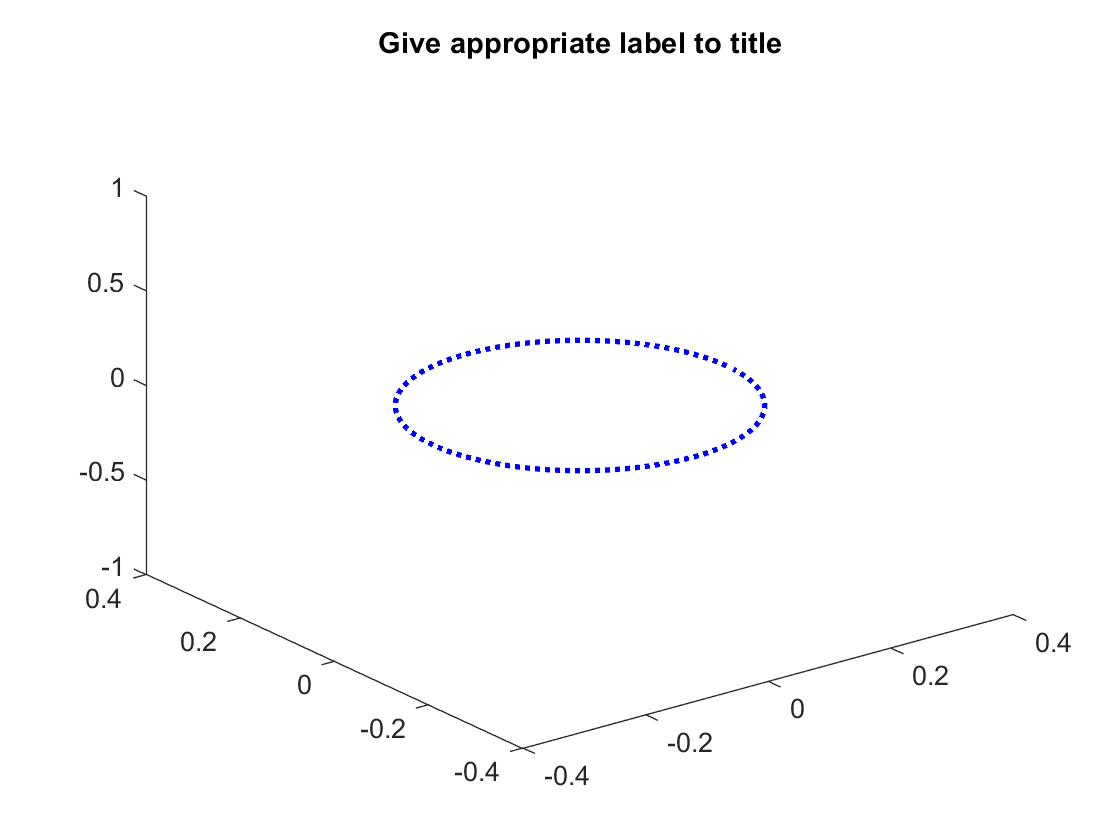

NumLocs = 100;                  % Number of locations
radius = 1.5/(2*pi);            % radius
d_theta = 2*pi./NumLocs;        % distance in radial coordinates
theta = d_theta*(0:NumLocs-1);
x=radius*cos(theta);            % Polar coordinates x
y=radius*sin(theta);            % Polar coordinates y
ground = zeros(1,NumLocs);      % Create the ring at rest potential
dx = 0.015;

R_i = .5;
a = 0.002;

% Test out 3D plot of a ring
plot3(x,y,ground,':b', 'LineWidth', 2);
title('Give appropriate label to title');

## Set up Initial Variables and Input Options

This is a simple interface using the input command to set up the 

disp('BME 445 Final Project Tasks')

BME 445 Final Project Tasks


mode_flag = input(...
    ['   Healthy mode         (press 1) ',...
    '\n   Unidirectional block (press 2) ',... 
    '\n   Your choice: ']);
% Lab 6 task - Consider adding later
% Uncomment below for Lab #6 (Apr 3), and add to above options.
%'\n   VFib model           (press 3) ',... 
%'\n   _________________    (press 4) ',...

% Uncomment below for Lab #6 (Apr 3)
% add_defib = input('Add Defibrillator? \n  Yes (press 1), \n  No  (press 0): ');

dur_total = input('Total duration of simulation? (ms, deault 40) ');

dt = 0.01;
numsteps = dur_total/dt;

## Set up regular stimulus currents for simulated heart beats

% Create first Stimuli 
I_stim1 = 250;
tdur = 1;
tdelay = 0;
Nstim_pos1 = 75;

% Create second Stimuli
I_stim2 = 350;
tdur2 = 1;
tdelay2 = input('Time of 2nd stimuli: ');
Nstim_pos2 = input('Location of 2nd stimuli: ');

Lab #6-7 - Debrillator code will be implemented in April.

%  This is the defibrillator variable.
I_defib = 350;
tdur3 = 1;
tdelay3 = 20;
Nstim3=1:100;

% Heart Stimulus after defibrillation that stabilizes the heart
I_stim4 = 350;
tdur4 = 1;
tdelay4 = 35;
Nstim4 = 75;

% Setting up the cable parameters.
v_m = ground;                      

C_m = 1; 
g_L_sup = 0.3; 
g_Na_sup = 120;  
g_K_sup = 36;  
e_K = -12.26;  
e_Na = 117.56;

## Initialize m, n, h parameters.

% Calculation of initial alpha and beta values.
m = alpha_m(v_m)./(alpha_m(v_m)+beta_m(v_m));
n = alpha_n(v_m)./(alpha_n(v_m)+beta_n(v_m));
h = alpha_h(v_m)./(alpha_h(v_m)+beta_h(v_m));

## Initialize conductivity and current values.

% Calculation of conductivity and current values

g_K = g_K_sup*n.^4;
g_Na = g_Na_sup*m.^3.*h;
g_L = g_L_sup*ones(1,NumLocs);

% Finding e_L
e_L = (ik(v_m,n,g_K,e_K) + ina(v_m,m,h,g_Na,e_Na))./g_L;

V = v_m; 
M = m;  N = n; H = h; G_k = g_K; G_na = g_Na;
I_na = ina(v_m,m,h,g_Na,e_Na);
I_k = ik(v_m,n,g_K,e_K);
I_l = il(v_m,g_L,e_L);

I_Na = I_na;
G_Na = I_na./(v_m-e_Na);

I_K = I_k;
G_K = G_k;

Iion = I_k + I_na + I_l;
I_S = ground;

## Lab #5 Task 2. This part of the code sets up the Cable Equations. 

% Matrix A will play a very important part of setting up 
% the cable equations for this Final Project.

% Setting up Matrix A:
b1 = 1; b2 = 2;
A = [-b2, b1, zeros(1,NumLocs-3), b1; b1, -b2, b1, zeros(1,NumLocs-3)];

for k = 3:NumLocs-1
    B = 0*linspace(1,NumLocs,NumLocs);
    B(k-1) = b1; B(k) = -b2; B(k+1) = b1;
    A = [A; B];
end

A = [A; [b1, [zeros(1,NumLocs-3)], b1,-b2]];
% Matrix A is set.

I_s = I_S;
coeff_A = a/(2*R_i*dx*dx)*ones(1,NumLocs);

## Lab 5 Task 3 - Modification for Unidirectional Block (Disease Model)

% unidirectional block (Disease)
if mode_flag == 2 || mode_flag == 3
    % In Lab #5, you are tasked to comment on the purpose of this modification.
    A(2,1) = 0;
    A(2,2) = -1;
end

## Implementing Forward Euler's Method

for k = 1:numsteps-1
% Solving for the present v_m
    v_0 = dt/C_m.*(coeff_A.*(A*v_m')' - Iion + I_s);
    v_m = v_m + v_0;
    V = [V; v_m];
    
% Runge-Kutta Algorithm for m, n, h
    m0 = rk_fcn('f_m',m,v_m,dt);
    n0 = rk_fcn('f_n',n,v_m,dt);
    h0 = rk_fcn('f_h',h,v_m,dt);
    
% Solving for next timestep for m, n, h.
    m = m + dt*m0;
    n = n + dt*n0;
    h = h + dt*h0;

    M = [M; m];
    N = [N; n];
    H = [H; h];

% solving for ion currents
    g_Na = g_Na_sup*m.^3.*h;
    I_na = g_Na.*(v_m-e_Na);
%    I_Na = [I_Na; I_na];
%    G_Na = [G_Na; g_Na];

    g_K = g_K_sup*n.^4;
    I_k = g_K.*(v_m-e_K);
%    I_K = [I_K; I_k];
%    G_K = [G_K; g_K];    

% Code for two stimuli
    if mode_flag == 1 || mode_flag == 2 
    %  healthy (1)    or unidirectional block (2)
        I_s = 0*linspace(1,2,NumLocs);
        if k > tdelay/dt && k <= (tdelay+tdur)/dt
            I_s(Nstim_pos1) = I_stim1;
        elseif k > tdelay2/dt && k <= (tdelay2+tdur2)/dt            
            I_s(Nstim_pos2) = I_stim2;
        end
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Lab 6 (April 3rd):  Your task is to 
        % develop a dedicated model for 
        % application of defibrillator here.
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
    end
        
    I_S = [I_S; I_s];
    Iion = I_k+I_na+I_l;
    waitbar(k/numsteps);
end

## Simulating the ring model

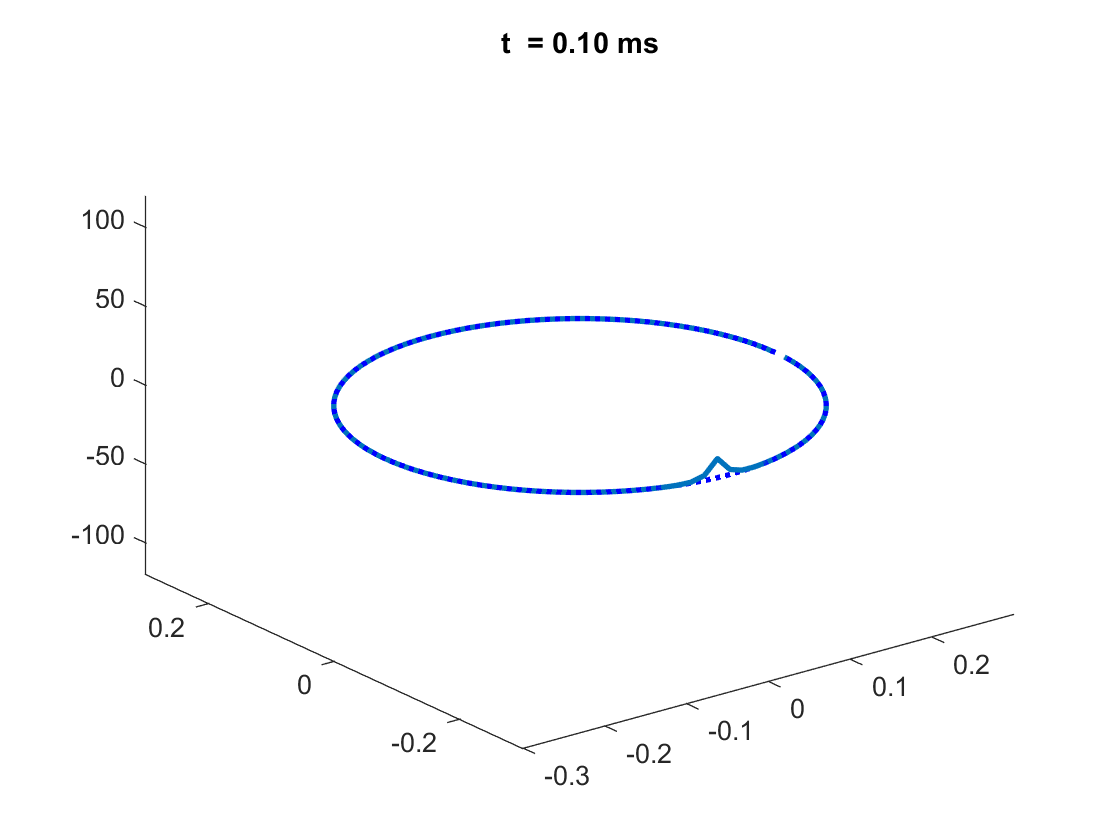

figure(445)

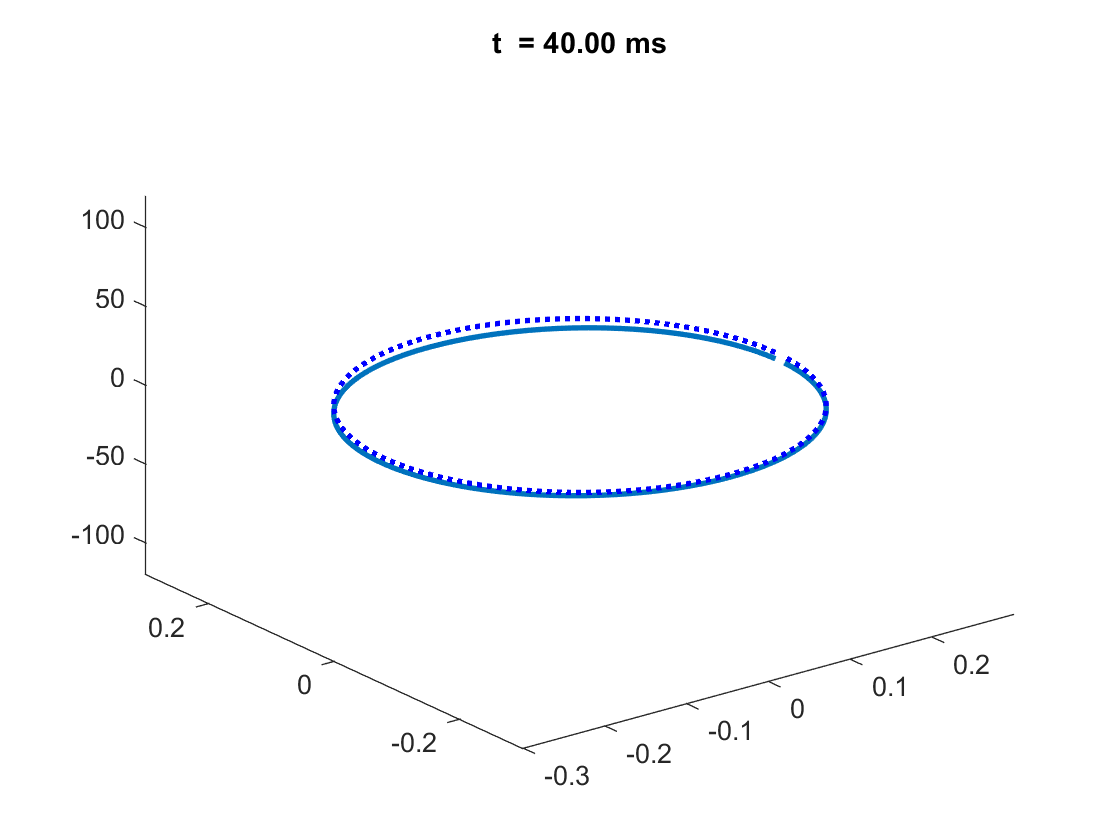

for k = 1:numsteps
    if mod(k,10) == 0
        plot3(x,y,V(k,:),x,y,ground,':b', 'LineWidth', 2);
        axis([-0.3 0.3 -0.3 0.3 -120 120]);
        title(sprintf('t  = %2.2f ms', k*dt));
        drawnow
    end
end


%This variable will be useful in obtaining extracellular potential measures
Time = linspace(0,dur_total-dt,numsteps); 

## Obtaining measurements from a probe

For Lab #7 (April 10-17), you will program an 'ECG Probe' to detect the measurements during this AP propagation from a point source.  

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Lab 7 (April 10th):  Your task is to 
% develop a point source to detect the 
% AP during this threshold stimuli.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Runge kutta function

function x0 = rk_fcn(fcn_str,x,v_m,dt)
    % m0 = rk_fcn('fcn_m',m,v_m,dt);
    x1 = eval(sprintf('%s(x,v_m);',fcn_str));
    x2 = eval(sprintf('%s(x+dt*x1/2,v_m);',fcn_str));
    x3 = eval(sprintf('%s(x+dt*x2/2,v_m);',fcn_str));
    x4 = eval(sprintf('%s(x+dt*x3,v_m);',fcn_str));
    x0 = (x1 + 2*x2 + 2*x3 + x4)/6;
end

% f_v.m
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function vp = f_v(v,m,n,h,I_stim, e_L)
% This is the differential equation for the membrane potential in 
% terms of the four currents and specific membrane capacitance C_m.

% Setting values into variables
C_m = 1; g_Na = 120;  g_K = 36;  e_K = -12.26;  e_Na = 117.56;

% Differential equation
vp = -1./C_m*(ina(v,m,h,g_Na,e_Na) + ik(v,n,g_K,e_K) + ...
il(v,e_L)+ I_stim);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% alpha_m.m, alpha_h.m, alpha_n.m
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function alpham = alpha_m(v_m)
% Alpha equation of m.

alpham = 0.1.*(25-v_m)./(exp((25-v_m)./10)-1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function alphah = alpha_h(v_m)
% Alpha equation of h.

alphah = 0.07.*exp(-v_m./20);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function alphan = alpha_n(v_m)
% Alpha equation of n.

alphan = 0.01.*(10-v_m)./(exp((10-v_m)./10)-1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

 
% beta_m.m, beta_h.m, beta_n.m
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function  betam = beta_m(v_m)
% Beta equation of m

betam = 4.0.*exp(-v_m./18.0);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function  betah = beta_h(v_m)
% Beta equation of h

betah = 1./(exp((30-v_m)./10)+1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function  betan = beta_n(v_m)
% Beta equation of n

betan = 0.125.*exp(-v_m./80.0);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% f_m.m, f_h.m, f_n.m
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function mp = f_m(m,v_m)
% Differential Equation of m

mp = alpha_m(v_m).*(1-m) - beta_m(v_m).*m;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function hp = f_h(h, v_m)
% Differential Equation of h

hp = alpha_h(v_m).*(1-h) - beta_h(v_m).*h;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function np = f_n(n, v_m)
% Differential Equation of n

np = alpha_n(v_m).*(1-n) - beta_n(v_m).*n;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function I_K = ik(v,n,g_K,e_K)

% g_K = 36;
% e_K = -12.26;
I_K = g_K*n.^4.*(v-e_K);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function I_Na = ina(v,m,h,g_Na,e_Na)

% g_Na = 120;
% e_Na = 117.56;
I_Na = g_Na.*m.^3.*h.*(v-e_Na);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function I_L = il(v, g_L, e_L)

% g_L = 0.3;
I_L = g_L.*(v-e_L);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%